# Predict Class Labels Using ClassificationEnsemble Predict Block

This example shows how to train an ensemble model with optimal hyperparameters, and then use the [ClassificationEnsemble Predict](docid:stats_ug#mw_5e0d9f14-6b9a-4323-8589-52c5b0b18043) block for label prediction in Simulink®. The block accepts an observation (predictor data) and returns the predicted class label and class score for the observation using the trained classification ensemble model. 

## Train Classification Model with Optimal Hyperparameters

Load the `CreditRating_Historical` data set. This data set contains customer IDs and their financial ratios, industry labels, and credit ratings. Determine the sample size.

tbl = readtable('CreditRating_Historical.dat');
n = numel(tbl)

Display the first three rows of the table.

head(tbl,3)

`tbl.Industry` is a categorical variable for an industry label. When you train a model for the ClassificationEnsemble Predict block, you must preprocess categorical predictors by using the `dummyvar` function to include the categorical predictors in the model. You cannot use the `'CategoricalPredictors'` name-value argument. Create dummy variables for `tbl.Industry`.

d = dummyvar(tbl.Industry);

`dummyvar` creates dummy variables for each category of `tbl.Industry`. Determine the number of categories in `tbl.Industry` and the number of dummy variables in `d`.

unique(tbl.Industry)'
size(d)

Create a numeric matrix for the predictor variables and a cell array for the response variable.

X = [table2array(tbl(:,2:6)) d];
Y = tbl.Rating;

`X` is a numeric matrix that contains 17 variables: the five financial ratios and the 12 dummy variables for the industry label. `X` does not use `tbl.ID` because the variable is not helpful in predicting credit ratings. `Y` is a cell array of character vectors that contains the corresponding credit ratings.

Suppose that you receive the data in sequence, and you have the first 3000 observations, but you have not received the last 932 yet. Partition the data into present and future samples.

prsntX = X(1:3000,:);
prsntY = Y(1:3000);
ftrX = X(3001:end,:);
ftrY = Y(3001:end);

Train an ensemble using all presently available data `prsntX` and `prsntY` with these options:

- Specify `'OptimizeHyperparameters'` as `'auto'` to train an ensemble with optimal hyperparameters. The `'auto'` option finds optimal values for `'Method'`,`'NumLearningCycles'`, and `'LearnRate'` (for applicable methods) of `fitcensemble` and `'MinLeafSize'` of tree learners. 

- For reproducibility, set the random seed and use the `'expected-improvement-plus'` acquisition function. Also, for reproducibility of the random forest algorithm, specify `'Reproducible'` as `true` for tree learners. 

- Specify the order of the classes by using the `'ClassNames'` name-value argument. The output values from the **score** port of the ClassificationEnsemble Predict block have the same order. 

rng('default')
t = templateTree('Reproducible',true);
ensMdl = fitcensemble(prsntX,prsntY, ...
    'ClassNames',{'AAA' 'AA' 'A' 'BBB' 'BB' 'B' 'CCC'}, ...
    'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

`fitcensemble` returns a [`ClassificationBaggedEnsemble`](docid:stats_ug#bsumopo-1) object because the function finds the random forest algorithm (`'Bag'`) as the optimal method.

## Create Simulink Model

This example provides the Simulink model `slexCreditRatingClassificationEnsemblePredictExample.slx`, which includes the [ClassificationEnsemble Predict](docid:stats_ug#mw_5e0d9f14-6b9a-4323-8589-52c5b0b18043) block. You can open the Simulink model or create a new model as described in this section.

Open the Simulink model `slexCreditRatingClassificationEnsemblePredictExample.slx`.

SimMdlName = 'slexCreditRatingClassificationEnsemblePredictExample'; 
open_system(SimMdlName)

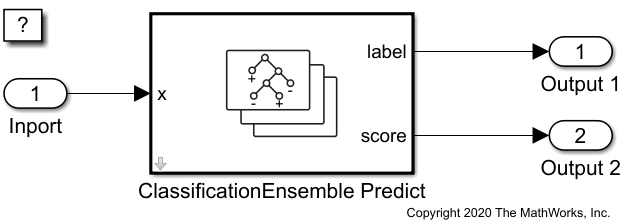

The `PreLoadFcn` callback function of `slexCreditRatingClassificationEnsemblePredictExample` includes code to load the sample data, train the model using the optimal hyperparameters, and create an input signal for the Simulink model. If you open the Simulink model, then the software runs the code in `PreLoadFcn` before loading the Simulink model. To view the callback function, in the **Setup** section on the **Modeling** tab, click **Model Settings** and select **Model Properties**. Then, on the **Callbacks** tab, select the `PreLoadFcn` callback function in the **Model callbacks** pane.

To create a new Simulink model, open the **Blank Model** template and add the ClassificationEnsemble Predict block. Add the Inport and Outport blocks and connect them to the ClassificationEnsemble Predict block. 

Double-click the ClassificationEnsemble Predict block to open the Block Parameters dialog box. Specify the **Select trained machine learning model** parameter as `ensMdl`, which is the name of a workspace variable that contains the trained model. Click the **Refresh** button. The dialog box displays the options used to train the model `ensMdl` under **Trained Machine Learning Model**. Select the **Add output port for predicted class scores** check box to add the second output port **score**.

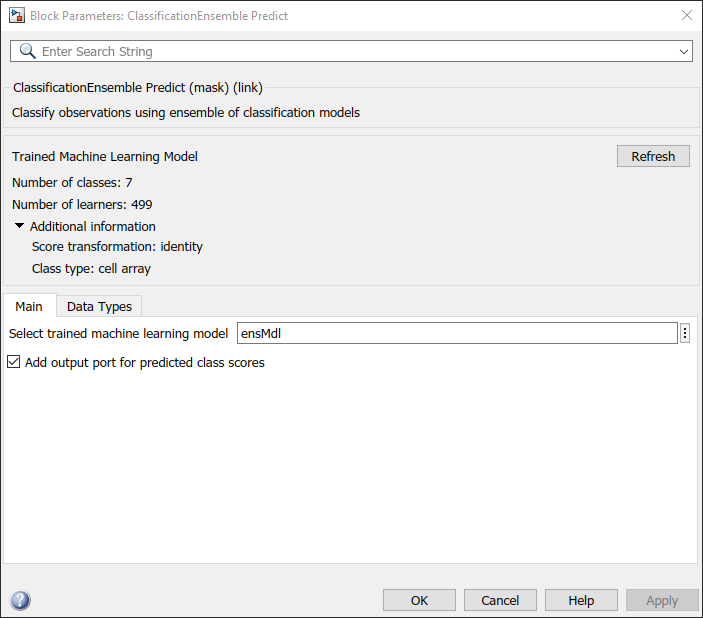

The ClassificationEnsemble Predict block expects an observation containing 17 predictor values. Double-click the Inport block, and set the **Port dimensions** to 17 on the **Signal Attributes** tab.

Create an input signal in the form of a structure array for the Simulink model. The structure array must contain these fields:

- `time` — The points in time at which the observations enter the model. In this example, the duration includes the integers from 0 through 931. The orientation must correspond to the observations in the predictor data. So, in this case, `time` must be a column vector.

- `signals` — A 1-by-1 structure array describing the input data and containing the fields `values` and `dimensions`, where `values` is a matrix of predictor data, and `dimensions` is the number of predictor variables.

 Create an appropriate structure array for future samples.

creditRatingInput.time = (0:931)';
creditRatingInput.signals(1).values = ftrX;
creditRatingInput.signals(1).dimensions = size(ftrX,2);

To import signal data from the workspace: 

- Open the Configuration Parameters dialog box. On the **Modeling** tab, click **Model Settings**.

- In the **Data Import/Export** pane, select the **Input** check box and enter `creditRatingInput` in the adjacent text box. 

- In the **Solver** pane, under **Simulation time**, set **Stop time** to `creditRatingInput.time(end)`. Under **Solver selection**, set **Type** to `Fixed-step`, and set **Solver** to `discrete (no continuous states)`.

For more details, see [Load Signal Data for Simulation](docid:simulink_doccenter#import-data).

Simulate the model.

sim(SimMdlName);

When the Inport block detects an observation, it directs the observation into the ClassificationEnsemble Predict block. You can use the [Simulation Data Inspector](docid:simulink_ref#mw_df415982-8312-413a-8c53-28d643c76e75) to view the logged data of the Outport blocks.

*Copyright 2020 The MathWorks, Inc.*